clc;
clear;
close all;
%% 读取数据
A=readmatrix("Regression.xlsx")

A =   253.0000  121.0000   18.0000   21.0000    1.0000
  370.0000  229.0000    6.0000    7.0000         0
  135.0000   75.0000   18.0000   21.0000    1.0000
  165.0000   89.0000   32.0000    8.0000    1.0000
  270.0000  132.0000   33.0000   21.0000    1.0000
  143.0000   73.0000   30.0000    8.0000    1.0000
  275.0000  127.0000   32.0000    9.0000    1.0000
  130.0000   73.0000   33.0000    9.0000    1.0000
  264.5000  131.0000   32.0000    9.0000    1.0000
  130.0000   73.0000   33.0000    6.0000    1.0000


y=A(:,1)

y =   253.0000
  370.0000
  135.0000
  165.0000
  270.0000
  143.0000
  275.0000
  130.0000
  264.5000
  130.0000


% 用的是三维线性回归
% 代表样本个数
x1=A(:,2); %房间平方
x2=A(:,3); %楼层
x3=A(:,4); %房龄
x4=A(:,5); %是否配套电梯
len = length(x1);
delta = ones(len,1);

%% 元素线性回归
x = [delta,x1, x2, x3];
[b,bint,r,rint,stats] = regress(y,x,0.05) % 95%的置信区间

b =    -6.6990
    1.7605
   -0.1257
    2.7773


bint =   -47.7143   34.3162
    1.5583    1.9627
   -0.9984    0.7470
    1.0477    4.5068


r =    -9.3798
  -45.1381
  -46.3976
   -3.1800
   -9.8597
    2.7363
   37.1444
  -12.6639
   19.6025
   -4.3320


rint =   -53.1595   34.3999
  -85.3083   -4.9680
  -86.6862   -6.1090
  -50.9347   44.5747
  -52.2474   32.5280
  -45.0624   50.5351
   -8.5526   82.8415
  -60.2348   34.9071
  -26.9055   66.1105
  -51.6672   43.0032


stats =     0.9130  160.9802    0.0000  570.3061



%%已知常数项和beita 1到4了，求函数
Y_NiHe = b(1) + b(2).*x1 + b(3).*x2 + b(4).*x3 %+b(3).*x4 ;

Y_NiHe =   262.3798
  415.1381
  181.3976
  168.1800
  279.8597
  140.2637
  237.8556
  142.6639
  244.8975
  134.3320


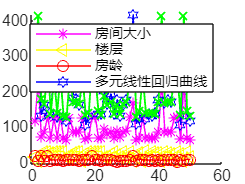


%% 可视化
figure(1);
hold on;
plot(x1, 'm*-');
plot(x2, 'y<-');
plot(x3, 'ro-');
%plot(x4);
plot(y,'bh-');
plot(Y_NiHe, 'gx-','LineWidth',1);
legend('房间大小','楼层','房龄','多元线性回归曲线')  

R_2 = sum( (Y_NiHe - y) .^ 2 ) ./ sum( (y - mean(y)) .^ 2 );
str= num2str(R_2);
disp(['拟合优度为:',str])

拟合优度为:0.086966


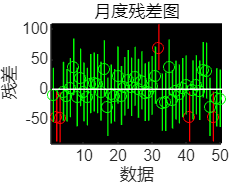


figure(2)
rcoplot(r,rint)%残差图
title('月度残差图')
xlabel('数据');ylabel('残差')


Y_NiHe = b(1) + b(2)*200 + b(3)*6 + b(4)*20

Y_NiHe = 400.1889